# ZROC CURVES 

## Load data

clear;
clc;

data_struct = loadData()

data_struct =   Map with properties:

        Count: 77
      KeyType: char
    ValueType: any


subjects = {'01RoYi','02XiHo','03JaVe','04NiSi','05PeYa','06KuSh',...
    '07AnWo','08LiBa', '09KeVa', '10MaIv', '11YaSi', '12JaGu',...
    '13ChSc','14SaMc','15ChFi', '16JoDa', '17IvSi','18LuHe','19ElBo','20MiLa',...
    '21ShZh', '22PeYe','23InMa','24WePi','25AyLe', '26DeCa','27LoLi',...
    '28WiTa', '29CrRa','30OrAl'};
toExclude = zeros(length(subjects),5);

## zROC

To compare type-I and type-II sensitivity between tasks and responses I plot the zROC curve for each task and subject. 

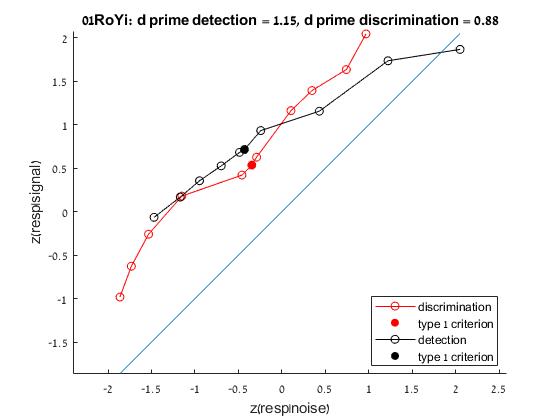

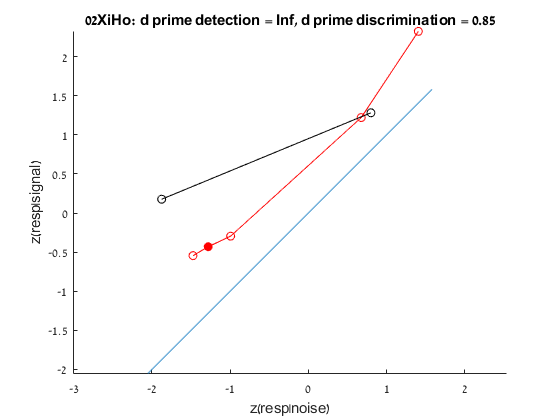

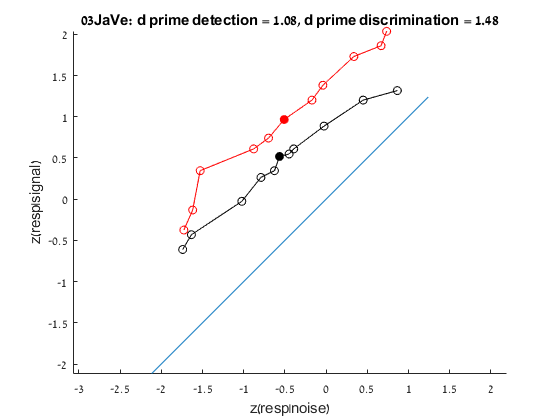

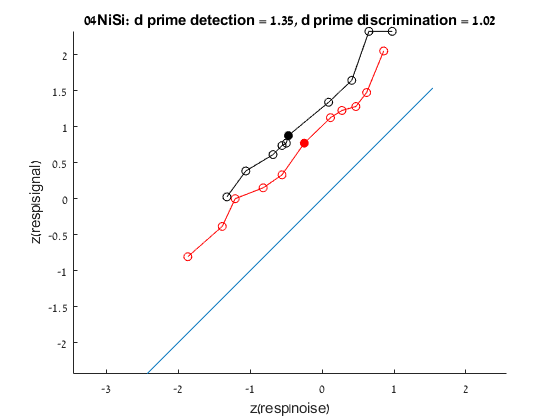

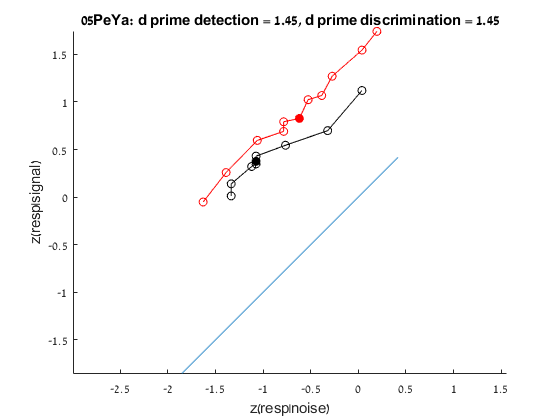

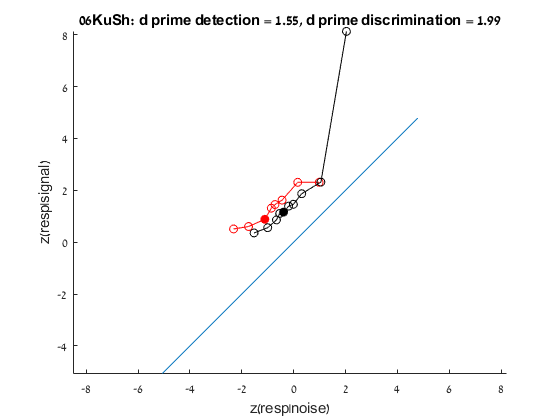

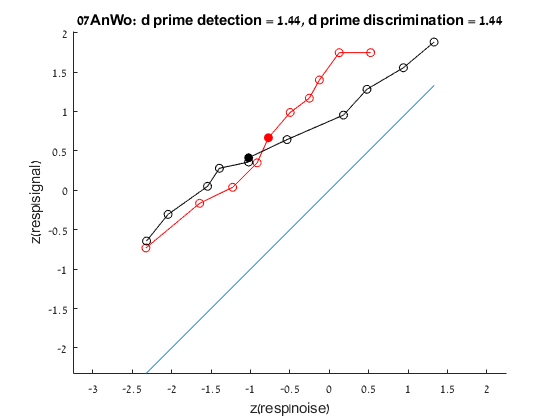

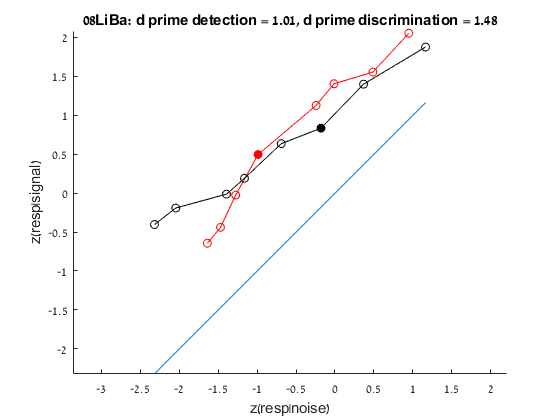

zDisS1G = [];
zDisS2G = [];
zDetSignalG = [];
zDetNoiseG = [];

nDetR_Noise = [];
nDetR_Signal = [];
nDisR_S1 = [];
nDisR_S2 = [];

for s=1:length(subjects)
    
    subject = data_struct(subjects{s});
    
    %bin all confidence ratings into 6 equally sized bins
    DisConfResponses = 2*(subject.DisResp-0.5).*subject.DisConf;
    DetConfResponses = 2*(subject.DetResp-0.5).*subject.DetConf;

    %create response count vectors, compute response probabilities 
    % and extract corresponding Z values
    DetSignalResponseCount = histc(DetConfResponses(subject.DetSignal==1), -6:6);
    pDetSignal = DetSignalResponseCount/sum(DetSignalResponseCount);
    zDetSignal = norminv(cumsum(pDetSignal(end:-1:2)));
    
    DetNoiseResponseCount = histc(DetConfResponses(subject.DetSignal==0), -6:6);
    pDetNoise = DetNoiseResponseCount/sum(DetNoiseResponseCount);
    zDetNoise = norminv(cumsum(pDetNoise(end:-1:2)));
    
    DisS1ResponseCount = histc(DisConfResponses(subject.DisSignal==1), -6:6);
    pDisS1 = DisS1ResponseCount/sum(DisS1ResponseCount);
    zDisS1 = norminv(cumsum(pDisS1(end:-1:2)));
    
    DisS2ResponseCount = histc(DisConfResponses(subject.DisSignal==0), -6:6);
    pDisS2 = DisS2ResponseCount/sum(DisS2ResponseCount);
    zDisS2 = norminv(cumsum(pDisS2(end:-1:2)));
    
    %plot
    figure;
    hold on;
    axis equal
    plot(zDisS2,zDisS1,'-or')
    scatter(zDisS2(6), zDisS1(6), 'red','filled')
    plot(zDetNoise, zDetSignal, '-ok')
    scatter(zDetNoise(6), zDetSignal(6),'black','filled')
    refline(1,0)    
    xlabel('z(resp|noise)');
    ylabel('z(resp|signal)');
    title(sprintf('%s: d prime detection = %.2f, d prime discrimination = %.2f', ...
        subjects{s}, zDetSignal(6)-zDetNoise(6), zDisS1(6)-zDisS2(6)));
    if s==1
        legend('discrimination','type 1 criterion', 'detection', 'type 1 criterion','Location','best')
    end
    
    zDisS1G = [zDisS1G; zDisS1'];
    zDisS2G = [zDisS2G; zDisS2'];
    zDetSignalG = [zDetSignalG; zDetSignal'];
    zDetNoiseG = [zDetNoiseG; zDetNoise'];
    
    nDetR_Noise = [nDetR_Noise; DetNoiseResponseCount'];
    nDetR_Signal = [nDetR_Signal; DetSignalResponseCount'];
    nDisR_S1 = [nDisR_S1; DisS1ResponseCount'];
    nDisR_S2 = [nDisR_S2; DisS2ResponseCount'];
end

## Group

 %plot
 zDisS1G(abs(zDisS1G)==inf)=nan;
 zDisS2G(abs(zDisS2G)==inf)=nan;
 zDetSignalG(abs(zDetSignalG)==inf)=nan;
 zDetNoiseG(abs(zDetNoiseG)==inf)=nan;
 
 good_subs = ~any(isnan([zDisS1G zDisS2G zDetSignalG zDetNoiseG]'))

good_subs = 1×30 logical array
   0   0   1   0   1   0   0   0   1   1   0   1   1   0   1   0   1   0   1   1   1   1   1   0   0   1   1   1   1   0


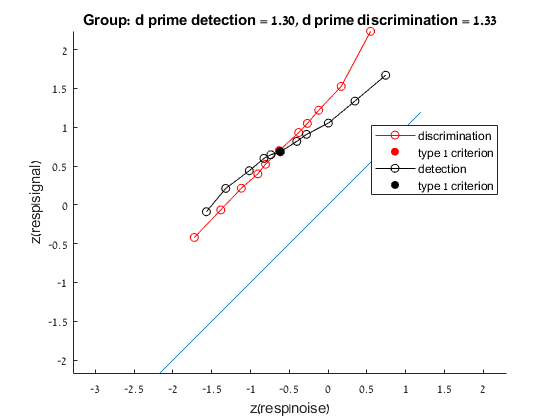

 zDisS1 = nanmean(zDisS1G(good_subs,:));
 zDisS2 = nanmean(zDisS2G(good_subs,:));
 zDetSignal = nanmean(zDetSignalG(good_subs,:));
 zDetNoise = nanmean(zDetNoiseG(good_subs,:));
 
    figure;
    hold on;
    axis equal
    plot(zDisS2,zDisS1,'-or')
    scatter(zDisS2(6), zDisS1(6), 'red','filled')
    plot(zDetNoise, zDetSignal, '-ok')
    scatter(zDetNoise(6), zDetSignal(6),'black','filled')
    refline(1,0)    
    xlabel('z(resp|noise)');
    ylabel('z(resp|signal)');
    title(sprintf('Group: d prime detection = %.2f, d prime discrimination = %.2f', ...
        zDetSignal(6)-zDetNoise(6), zDisS1(6)-zDisS2(6)));
         legend('discrimination','type 1 criterion', 'detection', 'type 1 criterion','Location','best')

%% LOAD DATA

clear all

nsubj = size(nDisR_S1,1);

Undefined function or variable 'nDisR_S1'.

nratings = size(nDisR_S1,2);

%% 1. EXTRACT RESPONSE CONDITIONAL ROCS

disS1S1 = nDisR_S1(:,1:6)./repmat(sum(nDisR_S1(:,1:6),2),1,nratings/2);
disS1S2 = nDisR_S1(:,12:-1:7)./repmat(sum(nDisR_S1(:,7:12),2),1,nratings/2);
disS2S1 = nDisR_S2(:,1:6)./repmat(sum(nDisR_S2(:,1:6),2),1,nratings/2);
disS2S2 = nDisR_S2(:,12:-1:7)./repmat(sum(nDisR_S2(:,7:12),2),1,nratings/2);

detNoiseNO = nDetR_Noise(:,1:6)./repmat(sum(nDetR_Noise(:,1:6),2),1,nratings/2);
detNoiseYES = nDetR_Noise(:,12:-1:7)./repmat(sum(nDetR_Noise(:,7:12),2),1,nratings/2);
detSignalNO = nDetR_Signal(:,1:6)./repmat(sum(nDetR_Signal(:,1:6),2),1,nratings/2);
detSignalYES = nDetR_Signal(:,12:-1:7)./repmat(sum(nDetR_Signal(:,7:12),2),1,nratings/2);

zDetHit = norminv(cumsum(detSignalYES,2));
zDetHit(isinf(zDetHit))=nan;

zDetFA = norminv(cumsum(detNoiseYES,2));
zDetFA(isinf(zDetFA))=nan;

zDetMiss = norminv(cumsum(detSignalNO,2));
zDetMiss(isinf(zDetMiss))=nan;

zDetCR = norminv(cumsum(detNoiseNO,2));
zDetCR(isinf(zDetCR))=nan;

zDisHit = norminv(cumsum(disS2S2,2));
zDisHit(isinf(zDisHit))=nan;

zDisFA = norminv(cumsum(catS1S2,2));
zDisFA(isinf(zDisFA))=nan;

zDisMiss = norminv(cumsum(disS2S1,2));
zDisMiss(isinf(zDisMiss))=nan;

zDisCR = norminv(cumsum(disS1S1,2));
zDisCR(isinf(zDisCR))=nan;

%% 2. FIT REGRESSION MODELS

detYES = [];
detNO = [];
detNOII = [];
disYES = [];
disNO = [];
disNOII = [];
for subj=1:nsubj
      detYESMat = [zDetFA(subj,:); zDetHit(subj,:)];
      detYESMat(:,any(isnan(detYESMat), 1)) = [];
      if size(detYESMat,2)<3
        detYES = [detYES; nan nan];
      else
        detYES = [detYES; polyfit(detYESMat(1,:)',detYESMat(2,:)',1)];
      end
      
      detNOMat = [zDetCR(subj,:); zDetMiss(subj,:)];
      detNOMat(:,any(isnan(detNOMat), 1)) = [];
      if size(detNOMat,2)<3
        detNO = [detNO; nan nan];
        detNOII = [detNOII; nan nan];
      else
        detNO = [detNO; polyfit(detNOMat(1,:)',detNOMat(2,:)',1)];
        detNOII = [detNOII; polyfit(detNOMat(2,:)',detNOMat(1,:)',1)];
      end
      
      disYESMat = [zDisFA(subj,:); zDisHit(subj,:)];
      disYESMat(:,any(isnan(disYESMat), 1)) = [];
      if size(disYESMat,2)<3
        disYES = [disYES; nan nan];
      else
        disYES = [disYES; polyfit(disYESMat(1,:)',disYESMat(2,:)',1)];
      end
      
      disNOMat = [zDisCR(subj,:); zDisMiss(subj,:)];
      disNOMat(:,any(isnan(disNOMat), 1)) = [];
      if size(disNOMat,2)<3
       disNO = [disNO; nan nan];
       disNOII = [disNOII; nan nan];
      else
        disNO = [disNO; polyfit(disNOMat(1,:)',disNOMat(2,:)',1)];
        disNOII = [disNOII; polyfit(disNOMat(2,:)',disNOMat(1,:)',1)];
      end
end

%% 3. PERFORM T TESTS

%%% assuming a typeI model:

% contrast slopes for detection
[~,pDetSlope,~,~] = ttest(detYES(:,1)-detNO(:,1))

% contrast slopes for categorization
[~,pCatSlope,~,~] = ttest(disYES(:,1)-disNO(:,1))

% contrast intercepts for detection. 
[~,pDetIntrcpt,~,~] = ttest(detYES(:,2)-detNO(:,2)) 

% contrast intercepts for categorization
[~,pCatIntrcpt,~,~] = ttest(disYES(:,2)-disNO(:,2))

%%% assuming a typeII model:

% contrast slopes for detection
[~,pDetSlopeII,~,~] = ttest(detYES(:,1)-detNOII(:,1))

% contrast slopes for categorization
[~,pCatSlopeII,~,~] = ttest(disYES(:,1)-disNOII(:,1))

% contrast intercepts for detection. 
[~,pDetIntrcptII,~,~] = ttest(detYES(:,2)-detNOII(:,2)) 

% contrast intercepts for categorization
[~,pCatIntrcptII,~,~] = ttest(disYES(:,2)-disNOII(:,2))